# Laboratorio di Automatica (prova del 27 Agosto 2018)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

August 27, 2018

Dept. of Information Engineering, University of Padova

## Esercizio 3

Sia 


$$P(s)\,=\, \frac{\Theta(s)}{U(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


la funzione di trasferimento di un motore elettrico in corrente continua, da ingresso in tensione $u$ espressa in $[V]$ ad uscita in *posizione* $\vartheta$ espressa in $[rad]$. Si supponga di controllare la *posizione* del motore con uno schema di controllo in catena chiusa a dati campionati del tipo mostrato in Fig. 2. 

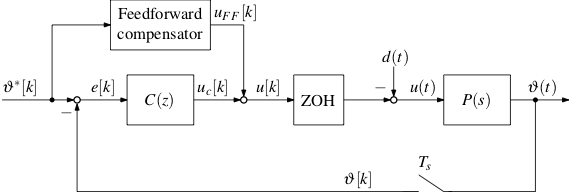

**Figura 2:** Sistema di controllo di posizione a dati campionati.

Si assuma che:

1)  il controllore digitale con funzione di trasferimento $C(z)$ sia ottenuto per discretizzazione, con il metodo di *Eulero all'indietro (backward Euler method)*, del seguente controllore PID a tempo continuo


$$C(s) \,=\, \frac{U(s)}{E(s)} \,=\; 
K_P \,+\, \frac{K_I}{s} \,+\, \frac{K_D\,s}{T_L\,s\,+\,1} $$


con 


$$K_P \,=\, 8.7\,,\qquad
K_I \,=\, 120.0\,,\qquad
K_D \,=\, 0.16\,,\qquad
T_L \,=\, 0.0053$$


dove l'errore di inseguimento $e[k]$ (ingresso del controllore) si assume espresso in $[\mathrm{rad}]$.

Per la discretizzazione, si consideri un periodo di campionamento pari a $T_s = 10\,ms$. Si ricorda che la funzione di trasferimento discretizzata si ottiene a partire dalla corrispondente funzione di trasferimento a tempo continuo mediante la sostituzione formale


$$s \,=\, \frac{1-z^{-1}}{T_s}$$


2)  l'uscita $u[k]$ del controllore saturi per valori eccedenti i limiti di $\pm 10\,V$.

3)  la misura di posizione $\vartheta[k]$ sia fornita da un encoder con risoluzione pari a $250\,\mathrm{ppr}$ (*ppr = pulses per rotation*, ovvero impulsi per giro).

4) il disturbo equivalente di tensione $d(t)$sia pari a $d(t) = d_0\,\mathrm{sign}(\omega)$, con $d_0 = 3.5\,\mathrm{V}$, e dove $\omega = d\vartheta/dt$ rappresenta la velocità del motore. 

Si svolgano i seguenti punti:

1)  Realizzare uno schema Simulink del sistema di controllo a dati campionati di Fig. 2.

*Note*: 

- per simulare sia il campionatore che lo Zero-Order Holder (ZOH), si faccia ricorso al blocco *Discrete *$\rightarrow$* Zero-Order Hold* della libreria di blocchi del Simulink.

- per simulare il disturbo, si utilizzi un blocco *Math Operations*$\rightarrow$* Sign,* facendo attenzione a deselezionare l'opzione "*Enable zero-crossing detection*" nei parametri del blocco *Sign* (doppio-click sul blocco per accedere ai suoi parametri).

*Soluzione.*

%   conversion gains
rad2deg = 180/pi;
deg2rad = pi/180;

%   plant parameters (in: driver voltage [V]; out: load position [rad])
km = 5.2;
Tm = 0.03;

%   sampling time
Ts = 0.01;

%   controller params
Kp = 8.7;
Ki = 120.0;
Kd = 0.16;
TL = 0.0053;

%   controller discretization ("real" derivative tf)
z = tf('z', Ts);  
s = (1-z^-1)/Ts;    %   backward Euler formal substitution
sysH = s/(TL*s+1);
[numH, denH] = tfdata(sysH, 'v');

%   encoder parameters
enc_ppr = 250;                  %  pulses per rotation
enc_pulse2deg = 360/enc_ppr;    %  quantization interval [deg/pulse]

%   input voltage disturbance amplitude
d0 = 3.5;

%   open model
open('ex3_sim1');

2)  Simulare la risposta del sistema di controllo a dati campionati con un riferimento di posizione sinusoidale di ampiezza pari a $A_r = 50\,\mathrm{deg}$ e frequenza $\omega_r = 2\,\pi\,\mathrm{rad/s}$ (si faccia attenzione ad usare le stesse unità di misura per il segnale di riferimento $\vartheta^*$ e l'uscita in posizione $\vartheta$). Si imposti un tempo finale di simulazione adeguato (ad esempio, $5\,\mathrm{s}$).

*Soluzione.*

%   step reference 
Ar = 50;
wr = 2*pi;

%    set simulation params
set_param('ex3_sim1', 'SolverType', 'Variable-step', ...
    'Solver', 'ode45', 'MaxStep', '0.01', 'StopTime','5');

%   run simulation
sim('ex3_sim1');

3)  Con riferimento alla simulazione eseguita al punto 2, mostrare in una figura Matlab gli andamenti dei seguenti segnali:

- *plot 1:* posizione misurata $\vartheta[k]$ e riferimento $\vartheta^*[k]$, entrambi espressi in $[deg]$ (gradi).

- *plot 2*: errore di inseguimento $e[k]$, espresso in $[deg]$.

- *plot 3*: tensione $u[k]$, espressa in $[V]$.

*Soluzione.*

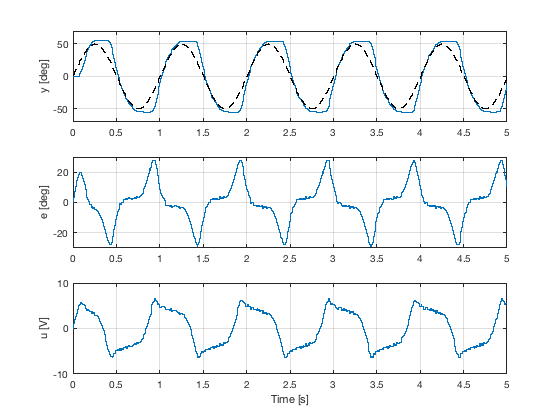

%   extract signals
t = simres.time;
y = simres.signals(1).values(:,1);
r = simres.signals(1).values(:,2);
e = simres.signals(2).values(:,1);
u = simres.signals(3).values(:,1);

%   plot results
figure;
subplot(3,1,1);
stairs(t, y);
hold on;
stairs(t, r, 'k--');
ylim([-70, 70]);
ylabel('y [deg]');
grid on;

subplot(3,1,2);
stairs(t, e);
ylim([-30, 30]);
ylabel('e [deg]');
grid on;

subplot(3,1,3);
stairs(t, u);
ylim([-10, 10]);
ylabel('u [V]');
xlabel('Time [s]');
grid on;

4) Per migliorare l'inseguimento del riferimento, si introduce un'azione di compensazione in feedforward del tipo:


$$u_{FF}[k] \;=\; \frac{T_m}{k_m}\,a^*[k] \,+\,\frac{1}{k_m}\,\omega^*[k]\,+\,d_0\,\mathrm{sign}\left(\omega^*[k] \right)   $$


dove $a^* = d\omega^*/dt$ e $\omega^* = d\vartheta^*/dt$ sono rispettivamente i riferimenti di accelerazione e velocità del motore, espressi in $[\mathrm{rad}/s^2]$ e $[\mathrm{rad}/s]$.

Modificare lo schema Simulink realizzato al punto 1 in modo da includere la compensazione in feedforward proposta.

*Soluzione.*

%    open Simulink model
open_system('ex3_sim2')

5) Simulare la risposta del sistema di controllo con compensazione in feedforward utilizzando il riferimento di velocità specificato al punto 2. Mostrare i risultati in modo analogo a quanto fatto al punto 3.

*Soluzione.*

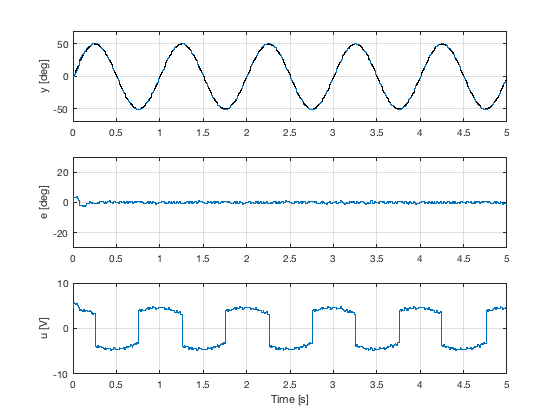

%    set simulation params
set_param('ex3_sim1', 'SolverType', 'Variable-step', ...
    'Solver', 'ode45', 'MaxStep', '0.01', 'StopTime','5');

%    run simulation
sim('ex3_sim2');

%   extract signals
t = simres.time;
y = simres.signals(1).values(:,1);
r = simres.signals(1).values(:,2);
e = simres.signals(2).values(:,1);
u = simres.signals(3).values(:,1);

%   plot results
figure;
subplot(3,1,1);
stairs(t, y);
hold on;
stairs(t, r, 'k--');
ylim([-70, 70]);
ylabel('y [deg]');
grid on;

subplot(3,1,2);
stairs(t, e);
ylim([-30, 30]);
ylabel('e [deg]');
grid on;

subplot(3,1,3);
stairs(t, u);
ylim([-10, 10]);
ylabel('u [V]');
xlabel('Time [s]');
grid on;